# [Solutions] NRG: Impurity spectral function

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the function for fdmNRG

The completed function, `getAdisc.m`, is added under the `NRG` directory. Compare with your version!

## Solution to (b): Temperature dependence of the impurity spectral function

Perform the preceding calculations for the fdmNRG.

clear

% Hamiltonian parameters
U = 4e-3; % Coulomb interaction at the impurity
epsd = -U/2; % impurity on-site energy
Delta0 = 2.5e-4; % hybridization strength
D = 1; % half-bandwidh
ozin = [-1;1]*D; % frequency grid to define the hybridization
RhoV2in = [1;1]*(Delta0/pi); % hybridization function on the ozin grid

% NRG parameters
Lambda = 2.5; % discretization parameter
N = 60; % length of the Wilson chain
Nkeep = 300;

% Wilson chain
[ff,gg] = doCLD(ozin,RhoV2in,Lambda,N);

% Construct local operators
[F,Z,S,I] = getLocalSpace('FermionS');

% Particle number operators
NF = cat(3,contract(conj(F(:,:,1)),3,[1 3],F(:,:,1),3,[1 3]), ...
           contract(conj(F(:,:,2)),3,[1 3],F(:,:,2),3,[1 3]));
       
% Impurity Hamiltonian
H0 = U*(NF(:,:,1)*NF(:,:,2)) + epsd*(NF(:,:,1)+NF(:,:,2));

% ket tensor for the impurity
A0 = getIdentity(1,2,I,2,[1 3 2]); % 1 for dummy leg

% iterative diagonalization
Inrg = NRG_IterDiag(H0,A0,Lambda,ff,F,gg,sum(NF,3),Z,Nkeep);

22-10-27 15:35:40 | NRG: start
22-10-27 15:35:40 | #00/60 : NK=4/4, EK=0/0
22-10-27 15:35:40 | #01/60 : NK=16/16, EK=0.04878/0.04878
22-10-27 15:35:40 | #02/60 : NK=64/64, EK=3.207/3.207
22-10-27 15:35:40 | #03/60 : NK=256/256, EK=6.221/6.221
22-10-27 15:35:40 | #04/60 : NK=328/1024, EK=4.999/13.01
22-10-27 15:35:41 | #05/60 : NK=304/1312, EK=4.681/9.125
22-10-27 15:35:41 | #06/60 : NK=328/1216, EK=5.009/10.56
22-10-27 15:35:41 | #07/60 : NK=304/1312, EK=4.741/9.182
22-10-27 15:35:41 | #08/60 : NK=328/1216, EK=5.038/10.6
22-10-27 15:35:42 | #09/60 : NK=304/1312, EK=4.852/9.268
22-10-27 15:35:42 | #10/60 : NK=328/1216, EK=5.109/10.7
22-10-27 15:35:42 | #11/60 : NK=304/1312, EK=5.048/9.432
22-10-27 15:35:42 | #12/60 : NK=328/1216, EK=5.265/10.92
22-10-27 15:35:43 | #13/60 : NK=300/1312, EK=5.305/9.782
22-10-27 15:35:43 | #14/60 : NK=328/1200, EK=5.554/11.22
22-10-27 15:35:43 | #15/60 : NK=320/1312, EK=5.712/10.54
22-10-27 15:35:43 | #16/60 : NK=306/1280, EK=5.863/11.25
22-10-27 15:35:44 


TK = 0.4107*sqrt(U*Delta0/2)*exp(-pi*U/8/Delta0 + pi*Delta0/2/U);

We consider a logarithmic grid of temperatures. Here, we compute the spectral functions only for spin-up for brevity, since the spin and particle-hole symmetries are respected in this example.

Ts = 10.^(0:-1:-10).';
Aconts = cell(1,numel(Ts));

for itT = (1:numel(Ts))
    Inrg = getRhoFDM(Inrg,Ts(itT));
    [odisc,Adisc] = getAdisc(Inrg,F(:,:,1),F(:,:,1),Z);
    [ocont,Aconts{itT}] = getAcont(odisc,Adisc,log(Lambda),Ts(itT)/5);
end

We don't show the message log since it's too long.

Let's plot the curves on a linear-log scale.

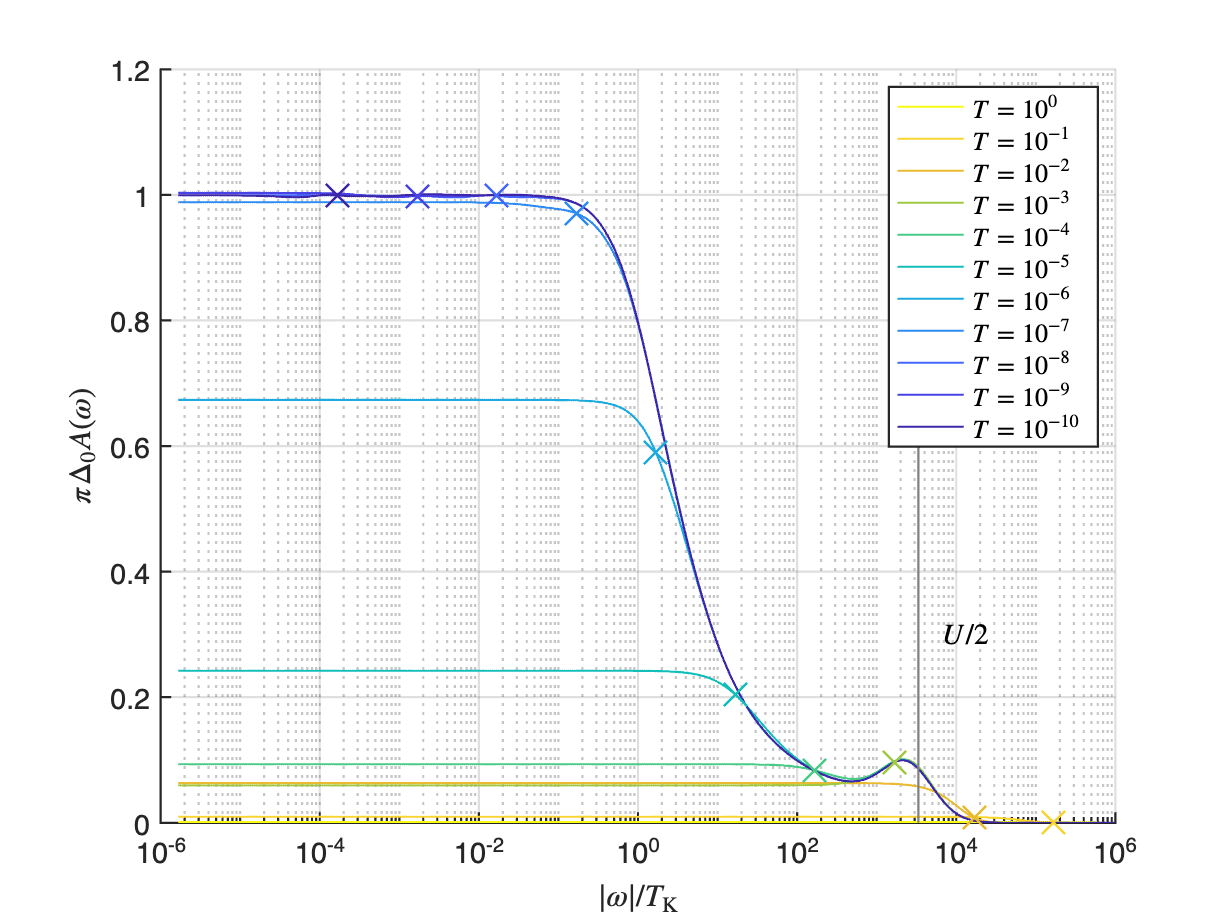

cmap = flipud(parula(numel(Ts)));
legs = cell(1,numel(Ts));
figure;
hold on;
for itT = (1:numel(Ts))
    plot(ocont(ocont>0)/TK,Aconts{itT}(ocont>0)*(pi*Delta0), ...
        'LineWidth',1,'LineStyle','-','Color',cmap(itT,:));
    legs{itT} = ['10^{',sprintf('%.4g',log10(Ts(itT))),'}'];
end
% mark the position of \omega = T
for itT = (1:numel(Ts))
    plot(Ts(itT)/TK,interp1(ocont,Aconts{itT},Ts(itT),'linear')*(pi*Delta0), ...
        'LineWidth',1,'Marker','x','MarkerSize',15,'Color',cmap(itT,:));
    legs{itT} = ['$T = 10^{',sprintf('%.4g',log10(Ts(itT))),'}$'];
end
% guide to the eye
plot(U/2/TK*[1 1],[0 1],'LineWidth',1,'LineStyle','-', ...
    'Color',[1 1 1]*0.5);
text(U/TK,0.3,'$U/2$','FontSize',13, ...
    'Interpreter','latex','HorizontalAlignment','left');
hold off;
set(gca,'FontSize',13,'LineWidth',1,'XScale','log');
legend(legs,'Interpreter','latex');
xlabel('$| \omega | / T_\mathrm{K}$','Interpreter','latex');
ylabel('$\pi \Delta_0 A(\omega)$','Interpreter','latex');
xlim([1e-6 1e6]);
grid on;

We find that the Kondo peak, which is of width $\sim T_\mathrm{K}$ and centered at $\omega = 0$, gets smeared out at higher temperatures $T > T_\mathrm{K}$. At even higher temperatures, $T > U$, the side peaks around $\omega = \pm U/2$ also get smeared out.

## Solution to Exercise (c): Dynamical susceptibilities

Before we compute the dynamical spin and charge susceptibilities, I will explain why we use the operator $\hat{n}_d - \langle \hat{n}_d \rangle$, not $\hat{n}_d$, to define the correlation function for the dynamical charge susceptibility. (Here $\hat{n}_d = \hat{n}_{d\uparrow} + \hat{n}_{d\downarrow}$ and $\langle \hat{n}_d \rangle$ denotes the average impurity occupation.) This subtraction is due to the definition of suscepbitilities in the linear response theory: A susceptibility indicates how much an observable of the system changes by adding a small perturbation to the system. This change is measured from the thermal expectation value with respect to the unperturbed system. Hence we subtract such expectation value $\langle \hat{n}_d \rangle$. On the other hand, for the spin susceptibility, we have $\langle \hat{S}_{d,z} \rangle = 0$ due to the spin symmetry in our example, so don't need the subtraction.

Also, please recall that, in the previous exercise on the conventional NRG scheme for computing the magnetic susceptibility, we have measured the variance of spin, i.e., $\langle (\hat{S}_z - \langle \hat{S}_z \rangle)^2 \rangle = \langle \hat{S}_z^2 \rangle - \langle \hat{S}_z \rangle$. 

This connection between the susceptibility and the variacne can be also seen from the spectral sum. Let's look at the Lehmann representation:.


$$A[\hat{O}_1, \hat{O}_2^\dagger] (\omega) = \sum_{s s'} ( \langle s | \hat{\rho} \hat{O}_1 | s' \rangle\!\langle s' | \hat{O}_2^\dagger | s \rangle \pm \langle s | \hat{O}_1 | s' \rangle\!\langle s' | \hat{\rho}  \hat{O}_2^\dagger | s \rangle) \, \delta ( \omega - (E_{s'} - E_{s}) ) .$$


The sum of the spectral weights from the first part in the summand ($\langle s | \hat{\rho} \hat{O}_1 | s' \rangle\!\langle s' | \hat{O}_2^\dagger | s \rangle$ coming before $\pm$) is $\mathrm{Tr} [ \hat{\rho} \hat{O}_1 \hat{O}_2^\dagger ]$ and the sum from the second part ($\langle s | \hat{O}_1 | s' \rangle\!\langle s' | \hat{\rho}  \hat{O}_2^\dagger | s \rangle$ coming after $\pm$) is $\mathrm{Tr} [ \hat{\rho} \hat{O}_2^\dagger \hat{O}_1  ]$. If the two operators $\hat{O}_1$ and $\hat{O}_2^\dagger$ commute, as for the spin and charge susceptibilities, the total sum $\mathrm{Tr} [ \hat{\rho} \hat{O}_1 \hat{O}_2^\dagger ] - \mathrm{Tr} [ \hat{\rho} \hat{O}_2^\dagger \hat{O}_1  ]$ vanishes. So we consider the sums from the first and second parts separately. We see that, if $\hat{O}_1 = \hat{O}_2^\dagger = \hat{n}_d - \langle \hat{n}_d \rangle$, then each sum from the first or second part becomes $\langle \hat{n}_d^2 \rangle - \langle \hat{n}_d \rangle^2$, which is the variance.

Let's compute the susceptibilities. We define the operator $\hat{n}_d - \langle \hat{n}_d \rangle$ by measuring the expectation value,

NF2 = sum(NF,3) - eye(size(NF,1))*trace(Inrg.RK{1}* ...
    updateLeft([],[],Inrg.AK{1},sum(NF,3),2,Inrg.AK{1}));
disp(NF2);

   -1.0000         0         0         0
         0    0.0000         0         0
         0         0    0.0000         0
         0         0         0    1.0000



We continue from the iterative diagonalization from the solution above. Note that we set the fourth input to `getAdisc` as empty (`[]`), to specify that the operators defining the correlation functions are bosonic, i.e., commuting.

Inrg = getRhoFDM(Inrg,Ts(end));

22-10-27 15:38:17 | Construct full density matrix @ T = 1e-10.
Elapsed time: 1.624s, CPU time: 11.03s, Avg # of cores: 6.793


% charge susceptibility
[odisc,Adisc1] = getAdisc(Inrg,NF2,NF2,[]); 

22-10-27 15:38:19 | Correlation function for commuting operators
22-10-27 15:38:19 | #00/60 : sum(Adisc) = 0
22-10-27 15:38:19 | #01/60 : sum(Adisc) = 0
22-10-27 15:38:19 | #02/60 : sum(Adisc) = 0
22-10-27 15:38:19 | #03/60 : sum(Adisc) = 0
22-10-27 15:38:19 | #04/60 : sum(Adisc) = 2.606e-22
22-10-27 15:38:19 | #05/60 : sum(Adisc) = 6.089e-20
22-10-27 15:38:19 | #06/60 : sum(Adisc) = 7.79e-19
22-10-27 15:38:19 | #07/60 : sum(Adisc) = 7.993e-19
22-10-27 15:38:19 | #08/60 : sum(Adisc) = 1.009e-18
22-10-27 15:38:20 | #09/60 : sum(Adisc) = 9.01e-19
22-10-27 15:38:20 | #10/60 : sum(Adisc) = -1.796e-18
22-10-27 15:38:20 | #11/60 : sum(Adisc) = -1.308e-18
22-10-27 15:38:20 | #12/60 : sum(Adisc) = -2.962e-18
22-10-27 15:38:20 | #13/60 : sum(Adisc) = -6.973e-18
22-10-27 15:38:20 | #14/60 : sum(Adisc) = 4.303e-18
22-10-27 15:38:21 | #15/60 : sum(Adisc) = 4.303e-18
22-10-27 15:38:21 | #16/60 : sum(Adisc) = 2.057e-17
22-10-27 15:38:21 | #17/60 : sum(Adisc) = 3.293e-17
22-10-27 15:38:21 | #18/60 : 

[ocont,Acont1] = getAcont(odisc,Adisc1,log(Lambda),Ts(end)/5);
% spin susceptibility
[~    ,Adisc2] = getAdisc(Inrg,S(:,:,2),S(:,:,2),[]);

22-10-27 15:38:29 | Correlation function for commuting operators
22-10-27 15:38:29 | #00/60 : sum(Adisc) = 0
22-10-27 15:38:29 | #01/60 : sum(Adisc) = 0
22-10-27 15:38:29 | #02/60 : sum(Adisc) = 0
22-10-27 15:38:29 | #03/60 : sum(Adisc) = 0
22-10-27 15:38:29 | #04/60 : sum(Adisc) = 4.966e-22
22-10-27 15:38:29 | #05/60 : sum(Adisc) = 3.749e-21
22-10-27 15:38:30 | #06/60 : sum(Adisc) = 9.348e-20
22-10-27 15:38:30 | #07/60 : sum(Adisc) = 1.138e-19
22-10-27 15:38:30 | #08/60 : sum(Adisc) = 2.019e-19
22-10-27 15:38:30 | #09/60 : sum(Adisc) = 2.188e-19
22-10-27 15:38:30 | #10/60 : sum(Adisc) = 6.638e-20
22-10-27 15:38:31 | #11/60 : sum(Adisc) = 3.307e-19
22-10-27 15:38:31 | #12/60 : sum(Adisc) = -7.874e-19
22-10-27 15:38:31 | #13/60 : sum(Adisc) = 1.341e-19
22-10-27 15:38:31 | #14/60 : sum(Adisc) = 9.744e-19
22-10-27 15:38:31 | #15/60 : sum(Adisc) = -1.926e-18
22-10-27 15:38:32 | #16/60 : sum(Adisc) = -7.564e-18
22-10-27 15:38:32 | #17/60 : sum(Adisc) = -4.094e-18
22-10-27 15:38:32 | #18/60 

[~    ,Acont2] = getAcont(odisc,Adisc2,log(Lambda),Ts(end)/5);

Note that the spectral sums are zeros up to numerical precision, as we discussed above.

disp([sum(Adisc1) sum(Adisc2)]);

   1.0e-16 *

   -0.1586    0.4583



We plot the curves on a log-log scale.

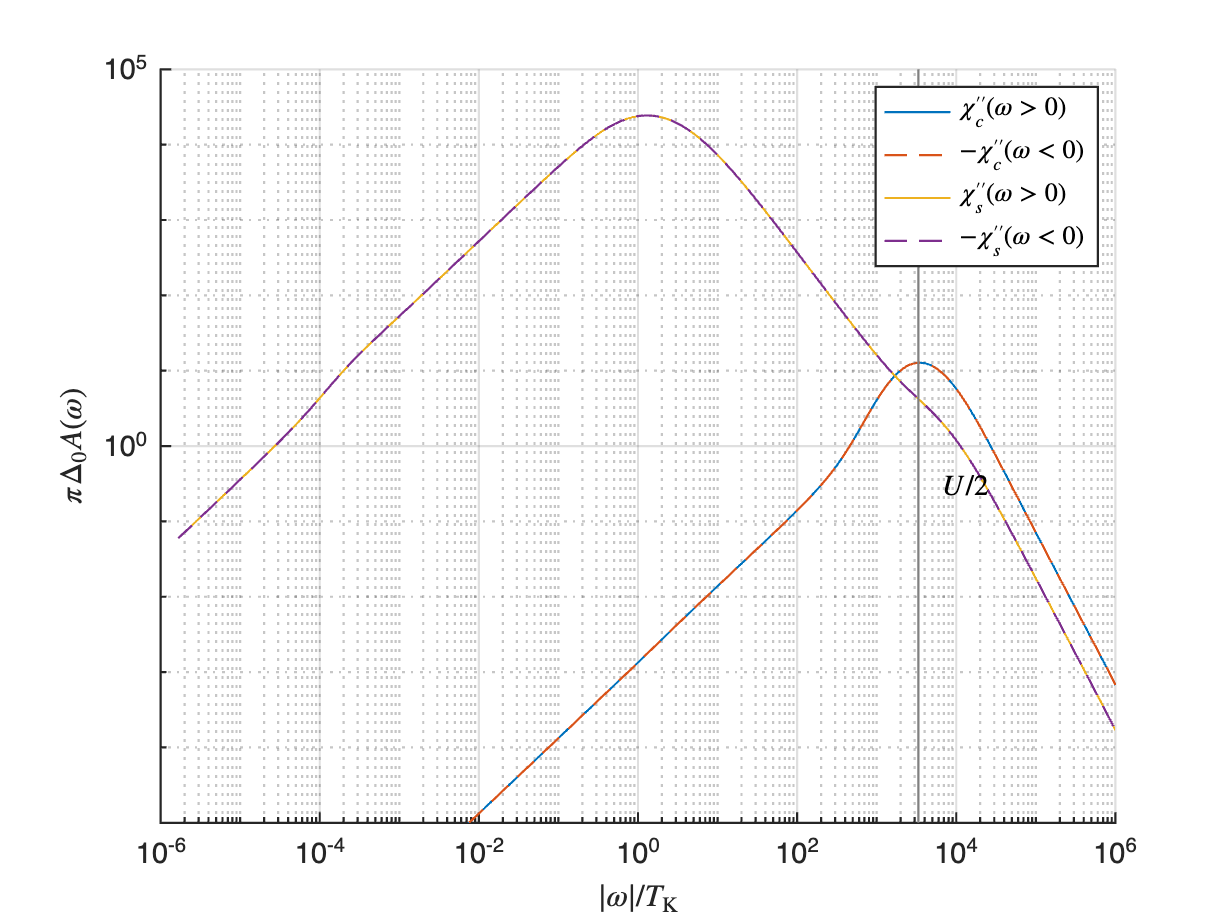

figure;
hold on;
plot(ocont(ocont>0)/TK,Acont1(ocont>0), ...
        'LineWidth',1,'LineStyle','-');
plot(-ocont(ocont<0)/TK,-Acont1(ocont<0), ...
        'LineWidth',1,'LineStyle','--');
plot(ocont(ocont>0)/TK,Acont2(ocont>0), ...
        'LineWidth',1,'LineStyle','-');
plot(-ocont(ocont<0)/TK,-Acont2(ocont<0), ...
        'LineWidth',1,'LineStyle','--');
% guide to the eye
plot(U/2/TK*[1 1],[1e-5 1e5],'LineWidth',1,'LineStyle','-', ...
    'Color',[1 1 1]*0.5);
text(U/TK,0.3,'$U/2$','FontSize',13, ...
    'Interpreter','latex','HorizontalAlignment','left');
hold off;
set(gca,'FontSize',13,'LineWidth',1,'XScale','log','YScale','log');
legend({'$\chi''''_c (\omega > 0)$','$-\chi''''_c (\omega < 0)$', ...
    '$\chi''''_s (\omega > 0)$','$-\chi''''_s (\omega < 0)$', ...
    },'Interpreter','latex');
xlabel('$| \omega | / T_\mathrm{K}$','Interpreter','latex');
ylabel('$\pi \Delta_0 A(\omega)$','Interpreter','latex');
xlim([1e-6 1e6]);
ylim([1e-5 1e5]);
grid on;

Note that the minus sign prefactor in $- \chi''_{s,c} (\omega < 0)$ to visualize the data for negative frequency. We see that the curve is an odd function, i.e., $\chi''_{s,c} (\omega) = - \chi''_{s,c} (-\omega)$. It is the generic property of the imaginary part of the correlation functions of bosonic operators.

We find that the spin susceptibility $\chi''_s$ is maximal around $\omega = T_\mathrm{K}$ and the charge susceptibility $\chi''_c$ is maximal around $\omega = U/2$. Indeed, the peak positions of $\chi''_c$ and $\chi''_s$ indicate, respectively, the energy scales associated with the crossovers from the free orbital regime to the local moment regime, and then from the local moment to the strong coupling regime.